clear all;
ts_s = 1/100;
eta=0.3;
simIn = Simulink.SimulationInput("tb_kinematics");
simIn = simIn.setVariable("eta_var",eta);
simIn = simIn.setVariable("openloop",0);
simIn = simIn.setVariable("kp_tuner",2);
simIn = simIn.setVariable("ki_tuner",0.8);
simIn = simIn.setVariable("Ts_s",ts_s);
out = sim(simIn); %run simulation, all results returned in "out"


% shape = zeros(2,size(out.tout,1));
kp_range =[0.5 , 0.8, 1 ,2 , 5 ] % 0.1:0.2:3.1

kp_range =     0.5000    0.8000    1.0000    2.0000    5.0000


ti_range = [ 1/20 , 1/44 , 1 /100 ] % 0.1:0.2:3.1

ti_range =     0.0500    0.0227    0.0100


eta_range = 0.1:0.1:0.3

eta_range =     0.1000    0.2000    0.3000


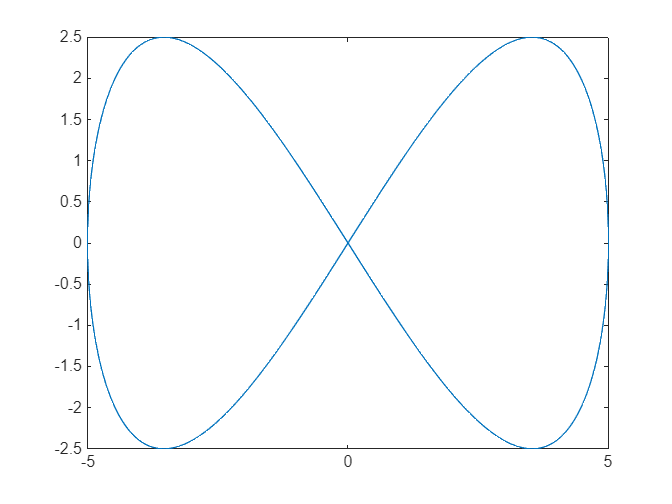

% ts_s = 1/50;
shape = [ out.xp_.Data'; out.yp_.Data' ];

plot(shape(1,:),shape(2,:))

size(kp_range,2)*size(ti_range,2)*size(eta_range,2)

ans = 45

 ns = size(kp_range,2)*size(ti_range,2);


tsV = simulink.multisim.Variable("Ts_s", ts_s);
kpV = simulink.multisim.Variable("kp_tuner", kp_range);
tiV = simulink.multisim.Variable("ki_tuner", ti_range);
olV = simulink.multisim.Variable("openloop", 0);
etaVal = simulink.multisim.Variable("eta", eta_range);



exhaustive = simulink.multisim.Exhaustive([kpV,  tiV, tsV, etaVal, olV]);
designStudy = simulink.multisim.DesignStudy("tb_kinematics", exhaustive);
% setModelParameter(designStudy,SimulationMode="rapid-accelerator");
Future = parsim(designStudy); %, "ShowSimulationManager","on");

[26-Jan-2025 14:38:51] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
[26-Jan-2025 14:39:25] Starting Simulink on parallel workers...
[26-Jan-2025 14:39:34] Configuring simulation cache folder on parallel workers...
[26-Jan-2025 14:39:35] Loading model on parallel workers...
[26-Jan-2025 14:39:48] Running simulations...


simOut = fetchOutputs(Future)

simOut = 1x45 Simulink.SimulationOutput array





 
 % 
% for i = 1:ns
% figure
% hold on
% plot(shape(1,:),shape(2,:))
% plot(simOut(1,i).xp.Data,simOut(1,i).yp.Data)
% title("KC: "+simOut(1,i).kc.Data+", TI: "+simOut(1,i).ti.Data)
% hold off
% 
% endhold onhold on


filetitle = "pdf_traj/" + string(datetime(now, 'ConvertFrom', 'datenum','Format','yyyy-MM-dd HH+mm+ss'));


for e = 0:(size(eta_range,2)-1)
    f = figure;
    f.Position  = [10 10 400*size(ti_range,2) 200*size(kp_range,2)];
    Tl = tiledlayout(size(ti_range,2),size(kp_range,2),'TileSpacing','Compact');

    for v = (e*ns +1):((e+1)*ns)
            nexttile
            hold on
            plot(shape(1,:),shape(2,:));
            plot(simOut(1,v).xp.Data,simOut(1,v).yp.Data)
            subtitle("KC: "+simOut(1,v).kc.Data+", TI: "+1/simOut(1,v).ki.Data);
            title("eta: "+simOut(1,v).eta.Data);
            hold off
    
    end

    title(Tl,"f: " + 1/ts_s + "Hz");
    % Tl.Title()title(Tl,'Computation time and path length comparison',"FontWeight","bold")
    exportgraphics(f,filetitle+".pdf",'ContentType','vector','Append',true);
end


% did = 0;
% for v = 1:ns
%     figure;
%     hold on
%     plot(shape(1,:),shape(2,:));
%     plot(simOut(1,v).xp.Data,simOut(1,v).yp.Data);
%     title("KC: "+simOut(1,v).kc.Data+", TI: "+simOut(1,v).ti.Data);
%     hold off
%     if (true)
%     ax = gca;
%     % exportgraphics(ax,'myfigure4.pdf');
%     % did = 1
%     end
% 
%     exportgraphics(ax,'myfigure5.pdf','Append',true);
% end